rng(73);

% comparing nuclear norm minimsation with the reweighted modification
n1 = 100;
n2 = 100;
r = 20;
P = binornd(1,0.7,[n1,n2])

P =      0     0     0     1     0     1     0     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     0     1     1     1     0     0     1     1     0     1     1     1     1     0     0     1     1     0     0     0     0
     1     1     0     1     1     0     1     1     0     1     0     1     1     0     0     1     0     1     1     0     1     1     0     1     1     0     1     0     1     0     1     1     0     1     0     1     1     1     1     1     1     1     1     1     0     1     0     0     1     1
     1     0     0     1     1     1     1     1     0     1     1     0     1     1     1     0     0     0     1     1     0     0     1     1     0     1     1     1     1     1     1     1     1     0     1     0     1     1     1     0     0     1     1     1     1     1     1     1     1     0
     0     0     1     1     1     1     0     1     0     0     0     1     0     1     1   

GT = rand([n1,r])*rand([r,n2])

GT =     6.0257    6.8388    5.4342    6.4442    7.0238    5.1304    5.7640    6.2607    5.9590    6.8175    6.1078    3.8004    7.1389    5.9981    6.7371    5.4549    6.0675    7.2669    6.0131    5.4657    7.0779    4.7191    7.5002    6.8855    5.8190    7.1140    5.8344    6.0123    5.9882    7.1702    6.4207    5.4268    5.5791    5.6098    4.9288    5.2751    6.0411    4.4477    5.6694    5.1235    5.4337    6.4100    5.6563    7.8060    5.8085    5.7012    6.5200    5.2575    5.5192    5.7433
    5.7055    5.2542    5.2214    5.4804    6.2626    5.2088    5.4443    5.6721    5.1685    4.9544    5.3615    3.0453    5.9204    5.0271    6.4076    4.3389    5.4940    6.1123    4.7371    5.1020    4.8978    3.7799    5.9493    5.2852    4.9641    6.3791    6.0369    5.0761    5.4144    5.4694    5.0726    4.8790    4.7088    5.8463    3.9348    4.3676    4.6861    3.8713    5.7312    5.0591    4.4231    5.3157    5.0660    6.6901    4.9223    5.1412    5.6951    4.2779    5.3260    

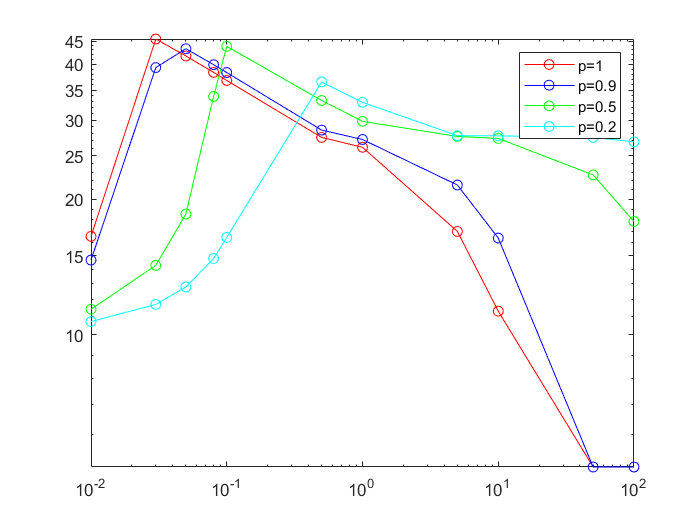

% effect of mu on algortihm performance
tau = 1.5;
max_iter = 100;
threshold = -1;
i = 0;
sigmas = [0.01,0.03,0.05,0.08 0.1,0.5,1,5,10,50,100];
psnr_1 = zeros(size(sigmas));
psnr_2 = zeros(size(sigmas));
psnr_3 = zeros(size(sigmas));
psnr_4 = zeros(size(sigmas));
rmse_1 = zeros(size(sigmas));
rmse_2 = zeros(size(sigmas));
rmse_3 = zeros(size(sigmas));
rmse_4 = zeros(size(sigmas));
for sigma_dash = sigmas
    i = i + 1;
    mu = (sqrt(n1)+sqrt(n2))*sqrt((sum(P,'all')/(n1*n2)))*sigma_dash;
    result_1 = fixed_point_minimization(P,GT, mu, tau, max_iter, threshold);
    result_2 = reweighted_fixed_point_minimization(P,GT, mu, tau, max_iter, threshold, 0.9);
    result_3 = reweighted_fixed_point_minimization(P,GT, mu, tau, max_iter, threshold, 0.5);
    result_4 = reweighted_fixed_point_minimization(P,GT, mu, tau, max_iter, threshold, 0.2);
    psnr_1(i) = PSNR(GT, result_1);
    psnr_2(i) = PSNR(GT, result_2);
    psnr_3(i) = PSNR(GT, result_3);
    psnr_4(i) = PSNR(GT, result_4);
    rmse_1(i) = RMSE(GT, result_1);
    rmse_2(i) = RMSE(GT, result_2);
    rmse_3(i) = RMSE(GT, result_3);
    rmse_4(i) = RMSE(GT, result_4);
end
loglog(sigmas, psnr_1,'-or', sigmas, psnr_2, '-ob',  sigmas, psnr_3, '-og', sigmas, psnr_4, '-oc')
legend('p=1','p=0.9', 'p=0.5', 'p=0.2')

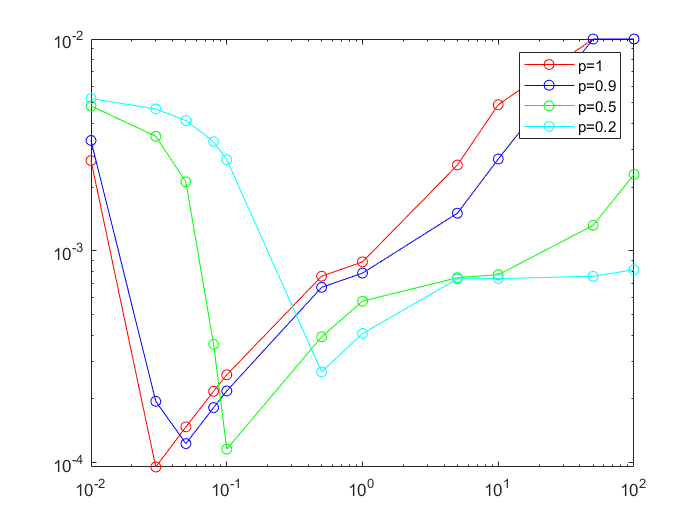


loglog(sigmas, rmse_1,'-or', sigmas, rmse_2, '-ob',  sigmas, rmse_3, '-og', sigmas, rmse_4, '-oc')
legend('p=1','p=0.9', 'p=0.5', 'p=0.2')

% function for soft shrinkage 

function result = soft_shrinkage(A, tau)
    [U, S, V] = svd(A);
    S(S>0) = S(S>0)-tau;
    S(S<0) = 0;
    result = U*S*V';
end

function [result, epsilon_new] = weighted_soft_shrinkage(A, tau, p, epsilon, gamma)
    [U, S, V] = svd(A);
    weights = ((S(S>0)) + epsilon).^(p-1);

    S(S>0) = S(S>0)-tau*weights;
    S(S<0) = 0;
    result = U*S*V';
    epsilon_new = min(epsilon, gamma*min(S(S>0),[],'all'));
    if size(epsilon_new,1) == 0
        epsilon_new = 0;
    end
end
function psnr = PSNR(true, recovered)
    H = size(true, 1);
    W = size(true, 2);
    C = size(true, 3);
    mse = (sum((true-recovered).^2,"all"))/(H*W*C);
    max_f = max(true,[], 'all');
    psnr = 20*log10(max_f/sqrt(mse));
end

function rmse = RMSE(true, recovered)
    H = size(true, 1);
    W = size(true, 2);
    C = size(true, 3);
    mse = (sum((true-recovered).^2,"all"))/(H*W*C);
    rmse = sqrt(mse/sum(true.^2, 'all'));
end
% algorithm for rank miniization problem
function result = fixed_point_minimization(P, GT, mu, tau, max_iterations, threshold)
    n1 = size(P, 1);
    n2 = size(P, 2);
    if max_iterations == -1
        max_iterations = 100;
    end
    if tau == -1
        tau = 1.5;
    end
    if threshold == -1
        threshold = 0.0001;
    end

    curr_iter = 0;
    Q_new = zeros(n1, n2);
    Q_prev = zeros(n1, n2);
    R = zeros(n1, n2);
    converged = false;
    convergence_num = 5; 
    curr_conv = 0;
    while curr_iter < max_iterations && not(converged)
        R = Q_prev - tau*(P.*(Q_prev - GT));
        Q_new = soft_shrinkage(R, tau*mu);
        if norm(Q_prev - Q_new, "fro") < threshold && norm(P.*(Q_prev - GT), "fro") < threshold
            curr_conv = curr_conv + 1;
        end
        if curr_conv == convergence_num
            converged = true;
            disp("Converged");
        end
        curr_iter = curr_iter + 1;
        Q_prev = Q_new;
    end
    result = Q_new;
end

% algorithm for rank miniization problem
function result = reweighted_fixed_point_minimization(P, GT, mu, tau, max_iterations, threshold, p)
    n1 = size(P, 1);
    n2 = size(P, 2);
    if max_iterations == -1
        max_iterations = 100;
    end
    if tau == -1
        tau = 1.5;
    end
    if threshold == -1
        threshold = 0.0001;
    end
    if p == -1
        p = 0.1;
    end
    
    curr_iter = 0;
    Q_new = zeros(n1, n2);
    Q_prev = zeros(n1, n2);
    R = zeros(n1, n2);
    converged = false;
    convergence_num = 5; 
    curr_conv = 0;
    epsilon = 0.01;
    gamma = 0.9;
    
    while curr_iter < max_iterations && not(converged)
        R = Q_prev - tau*(P.*(Q_prev - GT));
        [Q_new, epsilon] = weighted_soft_shrinkage(R, tau*mu, p, epsilon, gamma);
        if norm(Q_prev - Q_new, "fro") < threshold && norm(P.*(Q_prev - GT), "fro") < threshold
            curr_conv = curr_conv + 1;
        end
        if curr_conv == convergence_num
            converged = true;
            disp("Converged");
        end
        curr_iter = curr_iter + 1;
        Q_prev = Q_new;
    end
    result = Q_new;
end